# 3D isentropic inlet

clear; close; clc

## from the DESIGN CRITERIA FOR AXISYMMETRIC AND TWO-DIMENSIONAL SUPERSONIC INLETS AND EXITS - By James F. Connors and Rudolph C. Meyer

% this method does not have i finite thickness tip and is based on 2D
% method with thea_3D =  .83 * theta_2D as suggested in fleeman. this
% approximation works reasoanbly well but the location of the focus is
% wrong

%r and phi are coordinates
gamma = 1.4;
M_0 = 2; % free stream Mach number (~)
r_0 = 1; % something I choose?

figure


[x,y,nu] = QuasiIsentropic_Inlet_2D(M_0, 1, 1, gamma, 100);
M_f = 1

M_f = 1

r_f = 1;
n_points = 100

n_points = 100

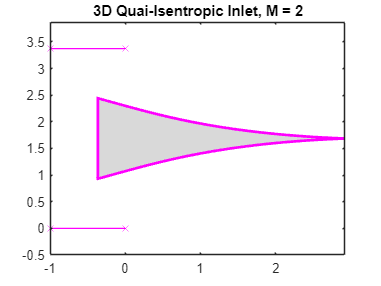


M= linspace(M_f,M_0,n_points); % mach numbers

% this method uses the 2d process and changes the flow angle using nu = .81
% nu from fleeman page 183
K = sqrt((gamma - 1) / (gamma + 1)); % parameter used in calculation
phi = 1/K * atan(K * sqrt(M.^2-1)); % angle of point location in polar coordiantes
mu = asin(1./M); % Mach anlge
nu = phi + mu - pi/2; % flow angle
nu = .81*nu; %convert 2D angles to 3D
r_2_r_0 = 1./(cos(K.*phi)).^6;
x = r_2_r_0 .* cos(mu - nu) * r_0;
y = r_2_r_0 .* sin(mu - nu) * r_0;

%plot(x,y); axis("equal"); xlim([0,max(x,[],"all")]); ylim([0,inf]);

%hold on

% plot the line of symmetry
x_sym = linspace(0,5);
y_sym = y(end) + -tan(nu(end)) * (x_sym - x(end));
%plot(x_sym,y_sym, "--r");

%figure
% now rotate into intitive coordinates
X = [x;y];
theta = -nu(end);
HFB = [cos(theta), sin(theta); -sin(theta), cos(theta)];
X_new = HFB*[x;y];
X_new_upper = -X_new(2,:) + 2*X_new(2,end); % compute the upper surface
%plot(X_new(1,:), X_new(2,:)); axis("equal"); %xlim([0,max(X_new(1,:),[],"all")]); ylim([0,inf]);

%figure;
axis("equal");
boundrayEdges_Xcoords = [X_new(1,:), fliplr(X_new(1,:))];
boundrayEdges_Ycoords = [X_new(2,:), fliplr(X_new_upper)];
fill(boundrayEdges_Xcoords, boundrayEdges_Ycoords, [.5,.5,.5], "FaceAlpha",.3, "EdgeColor",[1,0,1], "LineWidth",2, "DisplayName","g_2 infeasible region")


% locate and plot the inlet
hold on
X_inlet = [0;0];

% compute the location of the outer inlet rim
X_inlet_upper = X_inlet;
X_inlet_upper(2) = -X_inlet(2) + 2*X_new(2,end); % adjust the second point to be mirrored over the symmerty axis

% plot the inlet
plot([X_inlet(1),-1],[X_inlet(2),0], "Color",[1,0,1], "Marker","x")
plot([X_inlet_upper(1),-1],[X_inlet_upper(2),X_inlet_upper(2)], "Color",[1,0,1], "Marker","x")

xlim([-1,max(X_new(1,:),[],"all")]); ylim([-.5, X_inlet_upper(2)+.5]);

title(sprintf("3D Quai-Isentropic Inlet, M = %g",M_0))


Length_inlet = sqrt((X_inlet(1) - X_new(1,1)).^2 + (X_inlet(2) - X_new(2,1)).^2)

Length_inlet = 1

Length_inlet_2_r = Length_inlet / X_new(2,end)

Length_inlet_2_r = 0.5926